clear all
x = [129.2 125 126.8 130.1 130.5 130.6 127.4 125.2 ]' * 10^12

x = 1.0e+14 *

    1.2920
    1.2500
    1.2680
    1.3010
    1.3050
    1.3060
    1.2740
    1.2520


year1 = linspace(1.2 *10^12,1.5 *10^12,8)

year1 = 1.0e+12 *

    1.2000    1.2429    1.2857    1.3286    1.3714    1.4143    1.4571    1.5000


year = [2013 2014 2015 2016 2017 2018 2019 2020]

year =         2013        2014        2015        2016        2017        2018        2019        2020


f = polyfit(year,x,3)

f = 1.0e+21 *

   -0.0000    0.0000   -0.0021    1.4029


fitobjekt = fit(year',x,'poly1')

fitobjekt =      Linear model Poly1:
     fitobjekt(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -5e+10  (-9.916e+11, 8.916e+11)
       p2 =   2.289e+14  (-1.67e+15, 2.128e+15)

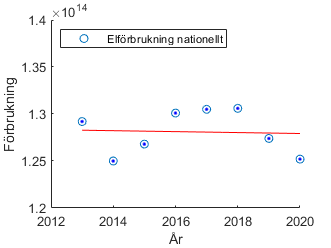

plot(year,x,'o')
box on
text(1:length(year),year,num2str(year'),'vert','bottom','horiz','center');
box off
hold on
%plot(year,polyval(f,year))
plot(fitobjekt,year,x)
ylim([1.2*10^14 1.4*10^14])
legend('Elförbrukning nationellt','Location','northwest')
ylabel('Förbrukning')
xlabel('År')